load sunspot.dat
yr = sunspot(:,1);
sunspotNumber = sunspot(:,2);

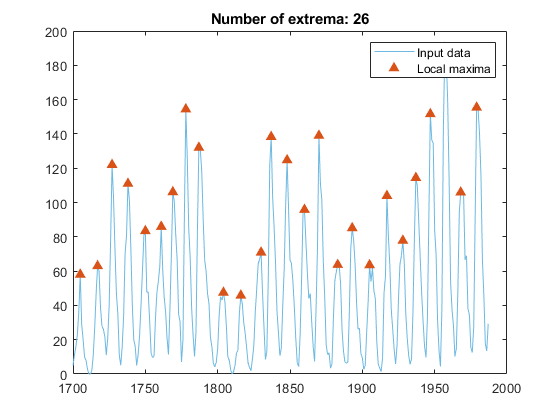

% Find local maxima
maxIndices = islocalmax(sunspotNumber,'MinSeparation',7,'SamplePoints',yr);

% Display results
clf
plot(yr,sunspotNumber,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(yr(maxIndices),sunspotNumber(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices))])
hold off
legend

peakDifferences = diff(yr(maxIndices))

peakDifferences =     12
    10
    11
    12
    11
     8
     9
     9
    17
    12



% Calculate the average
F0 = mean(peakDifferences)

F0 = 10.9600